%This is a test file for beam bending simulation

clear, close all


% Parameters
EI = 3;         % Bending stiffness
GJ = .7;
r = 5 / pi;        % Robot radius
n = 1;             % Number of segments
N = 50;         % Number of discretization points
% Initial actuator positions
act_11_start = [r; 0; 0; 1];
act_12_start = [r*cos(2*pi/3); r*sin(2*pi/3); 0; 1];
act_13_start = [r*cos(4*pi/3); r*sin(4*pi/3); 0; 1];
Base_coord = eye(4);


%Force applied at tip, N
Fx = 0.0; 
Fy = -0.02; 
Fz = -0.06;

%Moment applied at tip
Mx = 0;
My = 0;
Mz = 0;

%Actuator Lengths
L1 = 4;
L2 = 6;
L3 = 6;


%Turn plot on or off
ploton = false;


%Input function 
[p_def,p_init] = bending_3D(EI,GJ,r,N,L1,L2,L3,act_11_start,act_12_start,act_13_start,Base_coord,Fx,Fy,Fz,Mx,My,Mz,ploton);


%For now, I will use the function twice to generate two sets of points for
%two sensed actuator length sets

[~,p_pred] = bending_3D(EI,GJ,r,N,4,6,6,act_11_start,act_12_start,act_13_start,Base_coord,0,0,0,Mx,My,Mz,ploton);

[~,p_act] = bending_3D(EI,GJ,r,N,3.5,6.5,6.5,act_11_start,act_12_start,act_13_start,Base_coord,0,0,0,Mx,My,Mz,ploton);

%Now that I have these, I want to 

%Given input xdata and observed output ydata, find x
x0 = [0; 0; 0];

fun = @(x) bending_3D(EI,GJ,r,N,4,6,6,act_11_start,act_12_start,act_13_start,Base_coord,x(1),x(2),x(3),Mx,My,Mz,false)-p_act;

options = optimoptions(@lsqnonlin,'Algorithm','levenberg-marquardt');

ub = [1;1;1];
lb = [-1;-1;-1];

tic
test = lsqnonlin(fun,x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


test =     0.0152
    0.0000
   -0.0692


toc

Elapsed time is 1.703532 seconds.


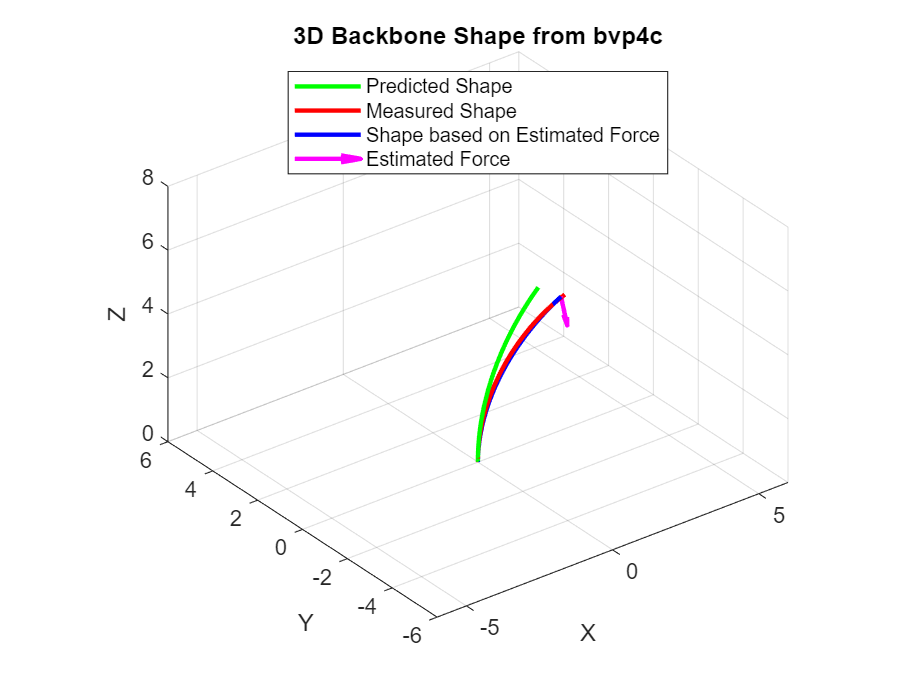



[p_act_2,~] = bending_3D(EI,GJ,r,N,4,6,6,act_11_start,act_12_start,act_13_start,Base_coord,test(1),test(2),test(3),Mx,My,Mz,ploton);

figure
% Plot deformed shape
plot3(p_pred(1,:), p_pred(2,:), p_pred(3,:), 'g-', 'LineWidth', 2);
hold on;
        
% Plot initial curved shape
plot3(p_act(1,:), p_act(2,:), p_act(3,:), 'r-', 'LineWidth', 2);

plot3(p_act_2(1,:), p_act_2(2,:), p_act_2(3,:), 'b-', 'LineWidth', 2);
        
title('Initial (Zero-Force) Curved Shape');
% Applied force arrow
quiver3(p_act_2(1,end), p_act_2(2,end), p_act_2(3,end), test(1)/sqrt(test(1)^2+test(2)^2+test(3)^2), test(2)/sqrt(test(1)^2+test(2)^2+test(3)^2), test(3)/sqrt(test(1)^2+test(2)^2+test(3)^2), ...
     'Color', 'magenta', 'LineWidth', 2, 'AutoScaleFactor', 1, 'MaxHeadSize', 10);
        
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
xlim([-6 6])
ylim([-6 6])
zlim([0 8])
title('3D Backbone Shape from bvp4c');
legend('Predicted Shape','Measured Shape',  'Shape based on Estimated Force','Estimated Force', 'Location', 'best');
        
        
        hold off

Functions



%Main function, gives deformed shape based on input force/moment and
%initial shape
function [p_def,p_init] = bending_3D(EI,GJ,r,N,L1,L2,L3,act_11_start,act_12_start,act_13_start,Base_coord,Fx,Fy,Fz,Mx,My,Mz,ploton)

    % Generate curvature and segment info
    [T, act1, act2, act3, curvature, Lck, beta, theta] = ...
        gen_transform_2(L1, L2, L3, r, act_11_start, act_12_start, act_13_start, Base_coord);
    
   
    
    s_vals = linspace(0, Lck, N);
    
    % Angle functions representing intrinsic curvature (constant curvature)
    theta_init = theta * ones(size(s_vals));               % Constant bending direction
    %phi_init = (pi/2) - beta * s_vals / Lck;
    %beta_init = beta * s_vals / Lck;      
    % Initialize position array
    p_init = zeros(3, N);
    
    %Compute curvature magnitude
    curvature_magnitude = beta / Lck;  % beta = total bending angle, radians; Lck = length
    
    %Use constant curvature magnitude for intrinsic curvature
    kappa0_vals = [ ...
        curvature_magnitude * cos(theta_init);   % no -pi/2 shift here
        curvature_magnitude * sin(theta_init);
        zeros(1, length(s_vals))];
    
    params.kappa0_fun = @(s) interp1(s_vals', kappa0_vals', s, 'linear', 'extrap')';
    
    %Update initial shape integration to accumulate bending angle linearly
    p_init(:,1) = [0;0;0]; % initialize first point
    
    for i = 2:N
        ds = s_vals(i) - s_vals(i-1);
        th = theta_init(i-1);
        
        % Bending angle up to s(i-1) from constant curvature
        bt = curvature_magnitude * s_vals(i-1);
    
        tangent = [sin(bt)*cos(th);
                   sin(bt)*sin(th);
                   cos(bt)];
        p_init(:, i) = p_init(:, i-1) + tangent * ds;
    end
    
    
    % External load applied at tip in global frame
    Fext = [Fx; Fy; Fz];    % force in X and Z directions
    Mext = [Mx; My; Mz];    % zero applied tip moment
    
    
    % Boundary conditions
    p_base = [0;0;0]; %Can change this later
    R_base = eye(3);
    n_tip = Fext;       % internal force at tip balances applied external force (Newton 3rd law)
    m_tip = Mext;       % internal moment at tip balances applied moment
    Kb = EI * eye(3);    % bending stiffness matrix (can be anisotropic)
    Kt = GJ;             % torsional stiffness scalar
    
    
    %Define Parameters for helper functions
    params.Kb = Kb;
    params.Kt = Kt;
    params.Fext = Fext;
    params.Mext = Mext;
    params.p_base = p_base;
    params.R_base = R_base;
    % Compute curvature vector at each s (in local frame)
    kappa0_vals = [ ...
        curvature_magnitude .* cos(theta_init - pi/2);
        curvature_magnitude .* sin(theta_init - pi/2);
        zeros(1, length(s_vals))];
    params.kappa0_fun = @(s) interp1(s_vals', kappa0_vals', s, 'linear', 'extrap')';
    params.n_tip = n_tip;
    params.m_tip = m_tip;
    
    % Initial guess
    solinit = bvpinit(linspace(0,Lck,N), @(s) cosserat_rod_guess(s, params));
    
    % Solve BVP
    sol = bvp4c(@(s,y) cosserat_rod_ode(s,y,params), @(ya,yb) cosserat_rod_bc(ya,yb,params), solinit);
    s_sol = linspace(0, Lck, N);
    y_sol = deval(sol, s_sol);
    %define deformed points
    p_def = y_sol(1:3,:);
    
    if ploton == true
        
        % Plot deformed shape
        plot3(p_def(1,:), p_def(2,:), p_def(3,:), 'b-', 'LineWidth', 2);
        hold on;
        
        % Plot initial curved shape
        plot3(p_init(1,:), p_init(2,:), p_init(3,:), 'r-', 'LineWidth', 2);
        
        title('Initial (Zero-Force) Curved Shape');
        % Applied force arrow
        quiver3(p_def(1,end), p_def(2,end), p_def(3,end), Fx/sqrt(Fx^2+Fy^2+Fz^2), Fy/sqrt(Fx^2+Fy^2+Fz^2), Fz/sqrt(Fx^2+Fy^2+Fz^2), ...
            'Color', 'green', 'LineWidth', 2, 'AutoScaleFactor', 1, 'MaxHeadSize', 10);
        
        xlabel('X'); ylabel('Y'); zlabel('Z');
        grid on; axis equal;
        xlim([-6 6])
        ylim([-6 6])
        zlim([0 8])
        title('3D Backbone Shape from bvp4c');
        legend('Deformed Shape','Initial Shape',  'Applied Force', 'Location', 'best');
        
        
        hold off
    end
end




%Helper function that makes skew symetric matrix
function S = skew(v)
    S = [   0   -v(3)  v(2);
          v(3)    0   -v(1);
         -v(2)  v(1)    0 ];
end

%Set of ODEs which determine shape under a force, based on Cosserat rod
%theory
%Right now, this ignores twist
function dy = cosserat_rod_ode(s, y, params)
    % Unpack parameters
    Kb = params.Kb;
    %kappa0 = params.kappa0;

    % Unpack state vector
    p = y(1:3);
    R = reshape(y(4:12), 3, 3);  % 3x3 rotation matrix
    n = y(13:15);                % internal force
    m = y(16:18);                % internal moment

    % Tangent vector is d3 (third column of R)
    t = R(:,3);

    % Calculate curvature vector
    kappa0 = params.kappa0_fun(s);  % dynamically evaluated
    kappa = Kb \ (m - Kb * kappa0);

    % Derivatives
    dp_ds = t;                            % position derivative
    dR_ds = R * skew(kappa);             % rotation derivative
    dn_ds = [0; 0; 0];                   % no distributed forces (lumped tip only)
    dm_ds = -cross(t, n);               % internal moment equilibrium

    % Pack derivatives
    dy = zeros(18,1);
    dy(1:3) = dp_ds;
    dy(4:12) = reshape(dR_ds, 9, 1);
    dy(13:15) = dn_ds;
    dy(16:18) = dm_ds;
end

%Boundary conditions for ODE solver
function res = cosserat_rod_bc(ya, yb, params)
    % Boundary conditions at base (s=0) and tip (s=L)

    p_base = params.p_base;
    R_base = params.R_base;
    n_tip = params.n_tip;
    m_tip = params.m_tip;

    res = [ ...
        ya(1:3) - p_base; ...          % base position fixed
        ya(4:12) - reshape(R_base,9,1); ... % base orientation fixed
        yb(13:15) - n_tip; ...         % tip internal force = external applied force
        yb(16:18) - m_tip ...          % tip internal moment = external applied moment
    ];
end


%Initial guess for ODE solver
function yinit = cosserat_rod_guess(s, params)
    % Interpolate intrinsic curvature at s
    kappa0 = params.kappa0_fun(s);
    
    % Integrate to get tangent vector (approximate)
    % Assuming constant theta and beta along s for simplicity
    beta_val = norm(kappa0) * s;  % angle of bending up to s
    if beta_val < 1e-6
        tangent = [0;0;1]; % nearly straight
    else
        theta_val = atan2(kappa0(2), kappa0(1));
        tangent = [sin(beta_val)*cos(theta_val);
                   sin(beta_val)*sin(theta_val);
                   cos(beta_val)];
    end
    
    % Approximate position
    p = tangent * s; % linear approx; you can improve by integrating

    % Approximate rotation: identity for simplicity
    R = eye(3);

    % Guess internal forces and moments
    n = params.n_tip;
    m = params.m_tip;

    yinit = [p; reshape(R,9,1); n; m];
end


%Kinematics function 
function [T_k, act_1_end, act_2_end, act_3_end, rho_k,L_ck,beta_k,theta_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, act_1_start, act_2_start, act_3_start, T_prev)

    phi_kj = 0; % fixed angle

    % calculate length
    L_ck = (L_k1 + L_k2 + L_k3)/3;
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);
    theta_k = atan2(3*(L_k2 - L_k3), sqrt(3)*(L_k2 + L_k3 - 2*L_k1));

    rho_k = beta_k/L_ck; % Curvature calc

    % Rotation matrix
    ct = cos(theta_k);
    st = sin(theta_k);
    cb = cos(beta_k);
    sb = sin(beta_k);

    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position vector
    P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];

    % Transformation matrix
    T_k = [R_k P_k; 0 0 0 1];
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
    end
    % actuator end point calculation
    act_1_end = T_prev*T_k*act_1_start;
    act_2_end = T_prev*T_k*act_2_start;
    act_3_end = T_prev*T_k*act_3_start;
end